# Data Organization

David Olson, 06 May 21

## Load Data

close all
clear all
clc

load('IMU1.mat')

#### X-Up X-Down Static Test

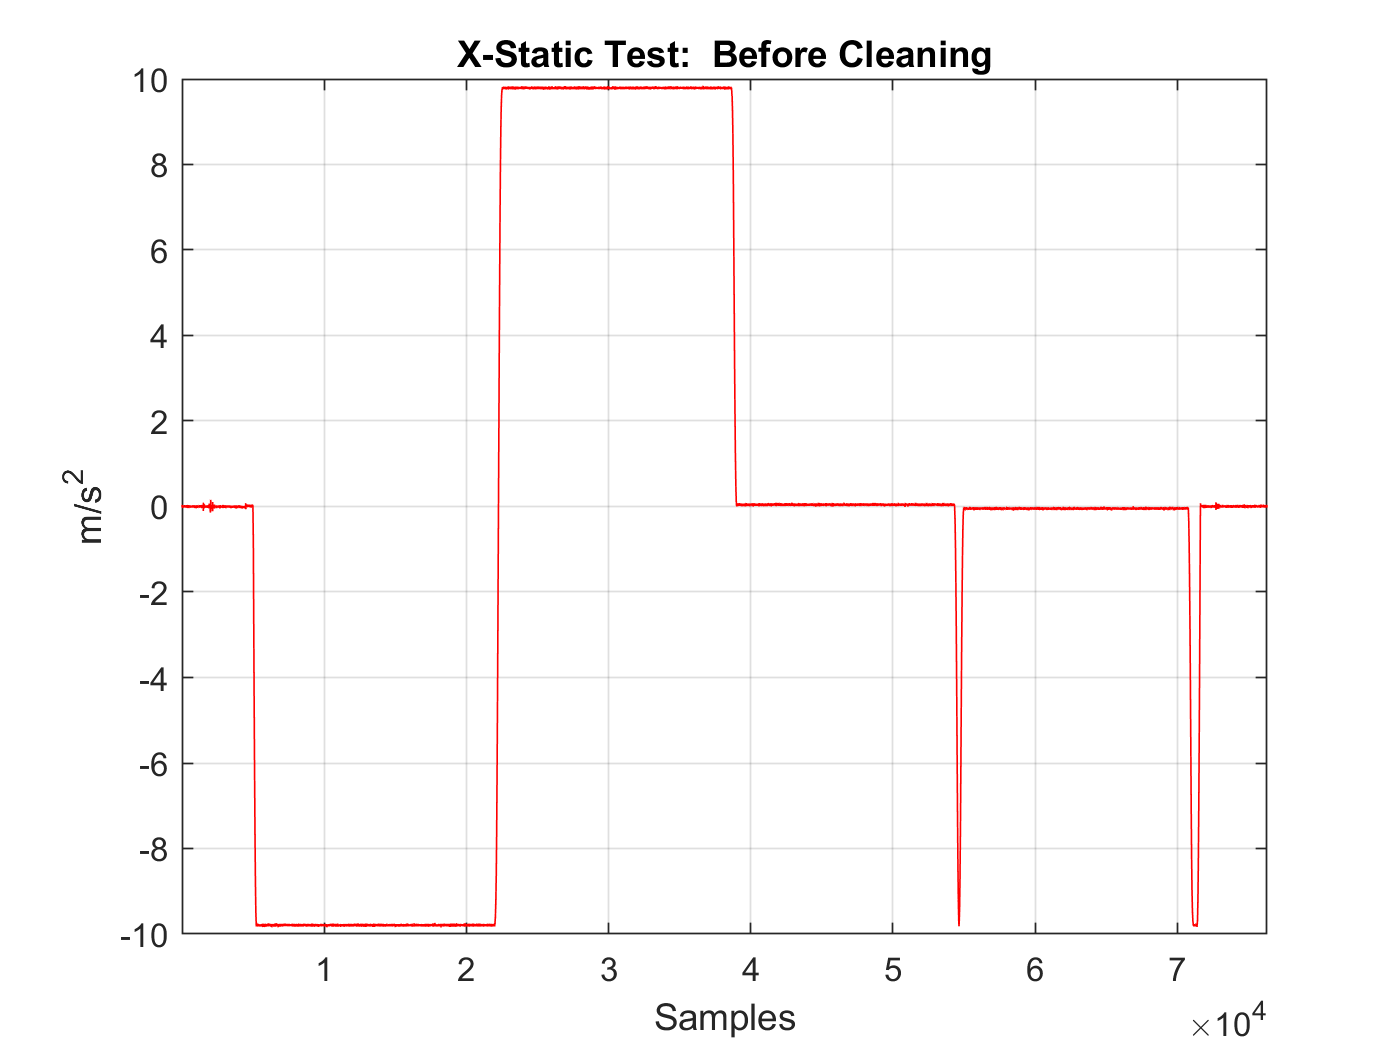

% Before Data Cleaning
x_a = staticxxyyIMU1(:,1);

figure
plot(x_a, 'r')
title('X-Static Test:  Before Cleaning')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(x_a)])
grid on

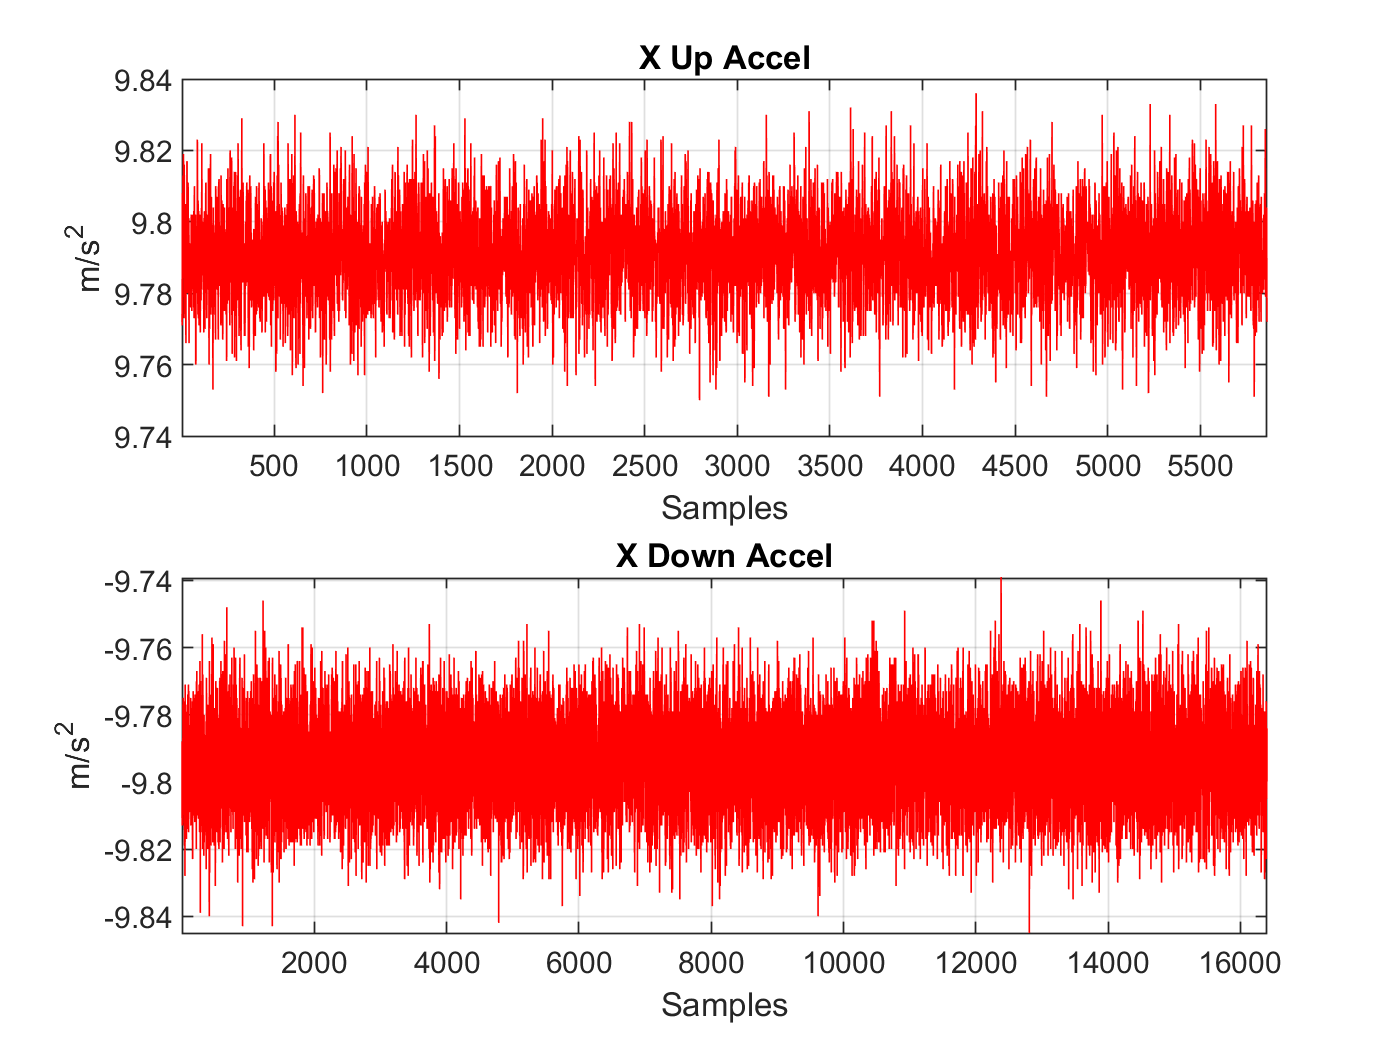


% Isolate X Up and X Down
x_up_accel = staticxxyyIMU1(22640:28500, :);
x_down_accel = staticxxyyIMU1(5400:21800, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(x_up_accel(:,1), 'r')
title('X Up Accel')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(x_up_accel)])
grid on
subplot(2,1,2)
plot(x_down_accel(:,1), 'r')
title('X Down Accel')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(x_down_accel)])
grid on


% Save Data
save('IMU1_accel_test.mat', 'x_up_accel', 'x_down_accel')

#### Y-Up Y-Down Static Test

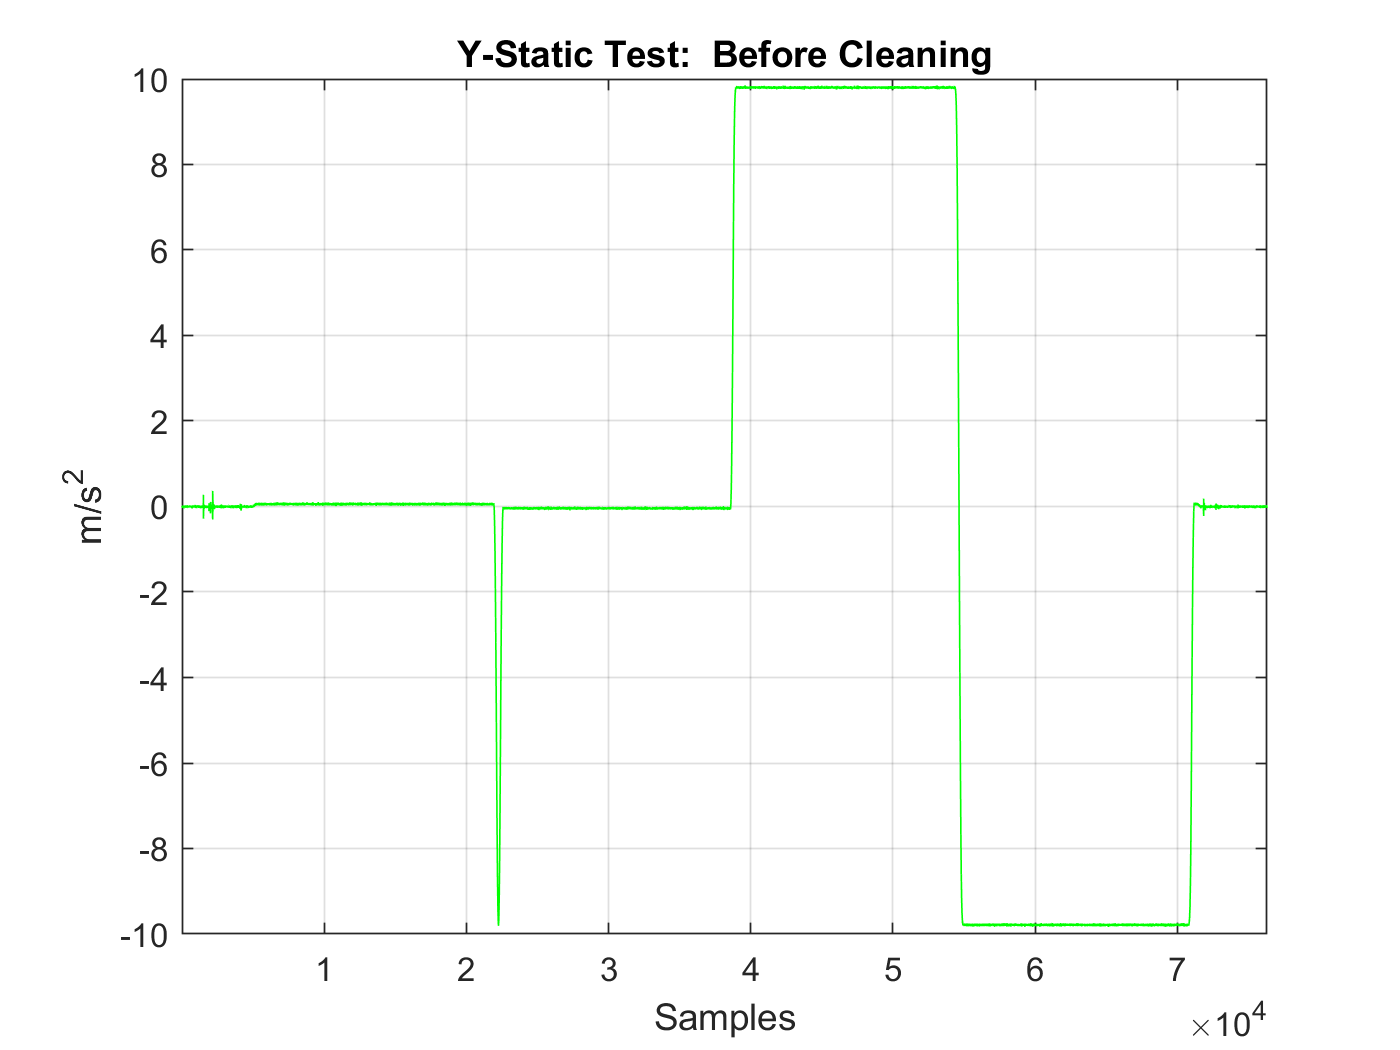

% Before Data Cleaning
y_a = staticxxyyIMU1(:,2);

figure
plot(y_a, 'g')
title('Y-Static Test:  Before Cleaning')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(y_a)])
grid on

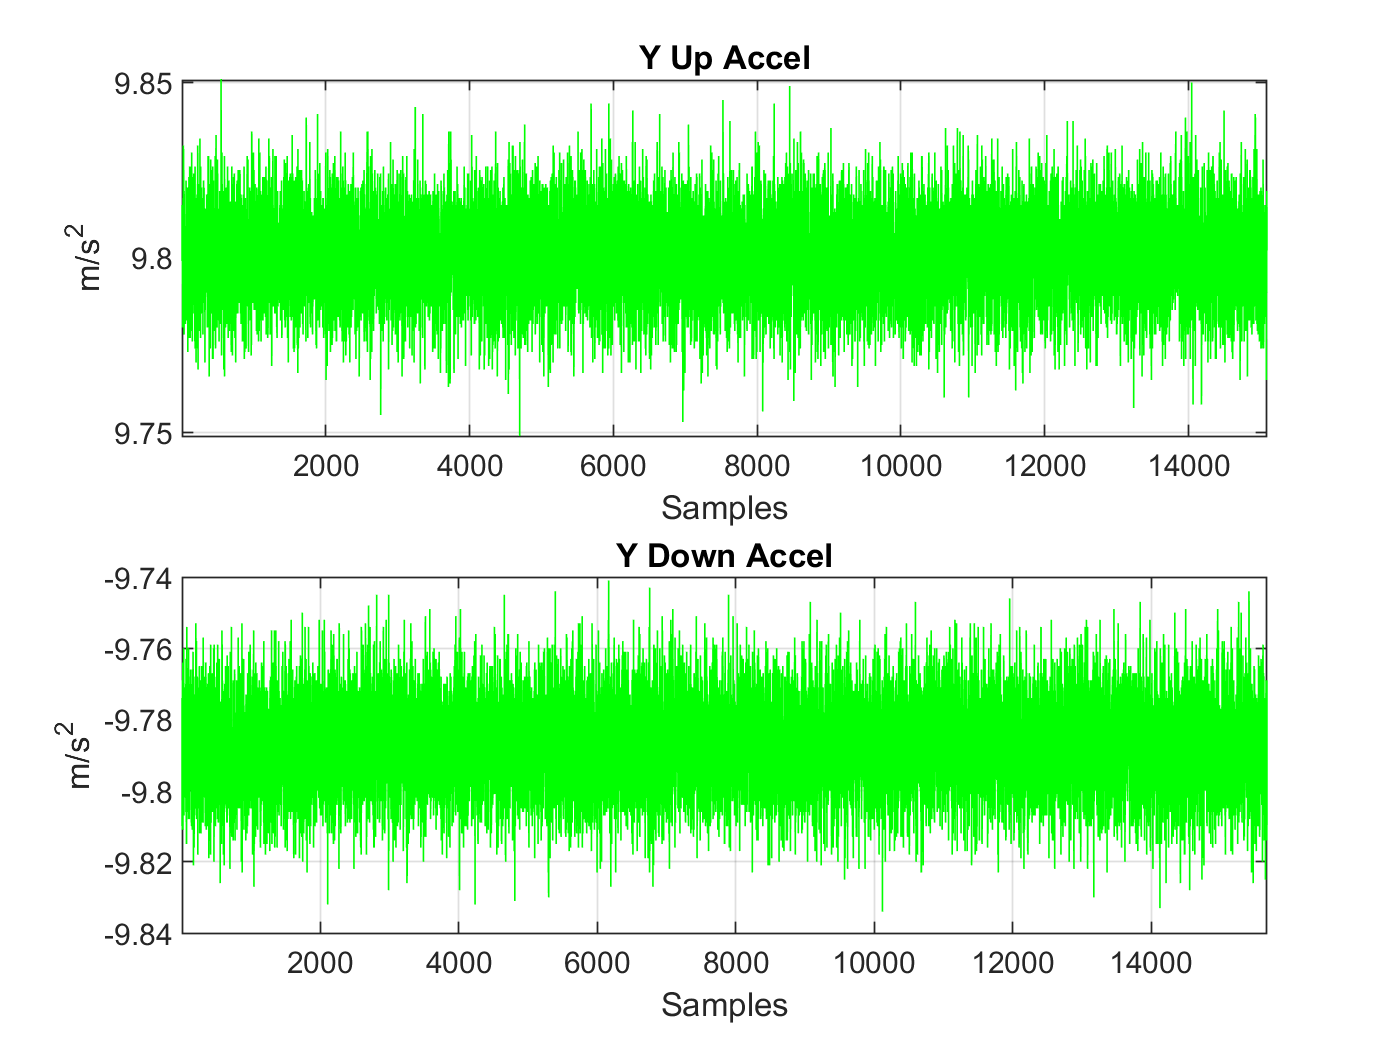


% Isolate Y Up and Y Down
y_up_accel = staticxxyyIMU1(39060:54150, :);
y_down_accel = staticxxyyIMU1(55030:70700, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(y_up_accel(:,2), 'g')
title('Y Up Accel')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(y_up_accel)])
grid on
subplot(2,1,2)
plot(y_down_accel(:,2), 'g')
title('Y Down Accel')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(y_down_accel)])
grid on


% Save Data
save('IMU1_accel_test.mat', 'y_up_accel', 'y_down_accel', '-append')

#### Z-Up Z-Down Static Test

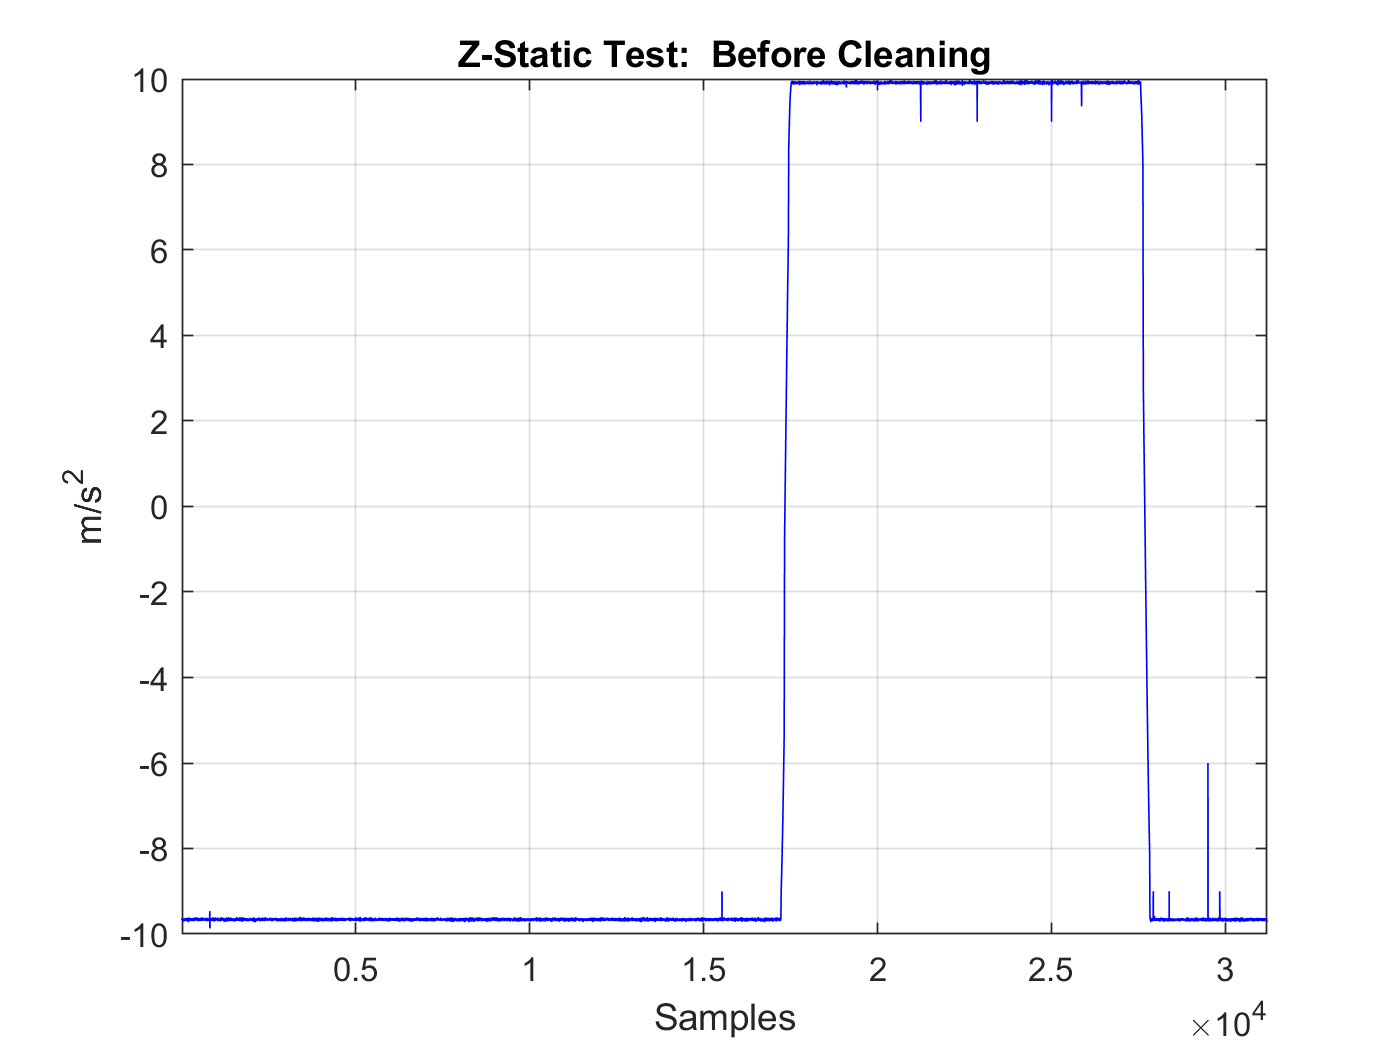

% Data Cleaning
mask1 = abs(staticzzIMU1(:,3)) < 11;
staticzzIMU1 = staticzzIMU1(mask1, :);
mask2 = staticzzIMU1(:,3) ~= 0;
staticzzIMU1 = staticzzIMU1(mask2, :);
z_a = staticzzIMU1(:,3);

figure
plot(z_a, 'b')
title('Z-Static Test:  Before Cleaning')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(z_a)])
grid on

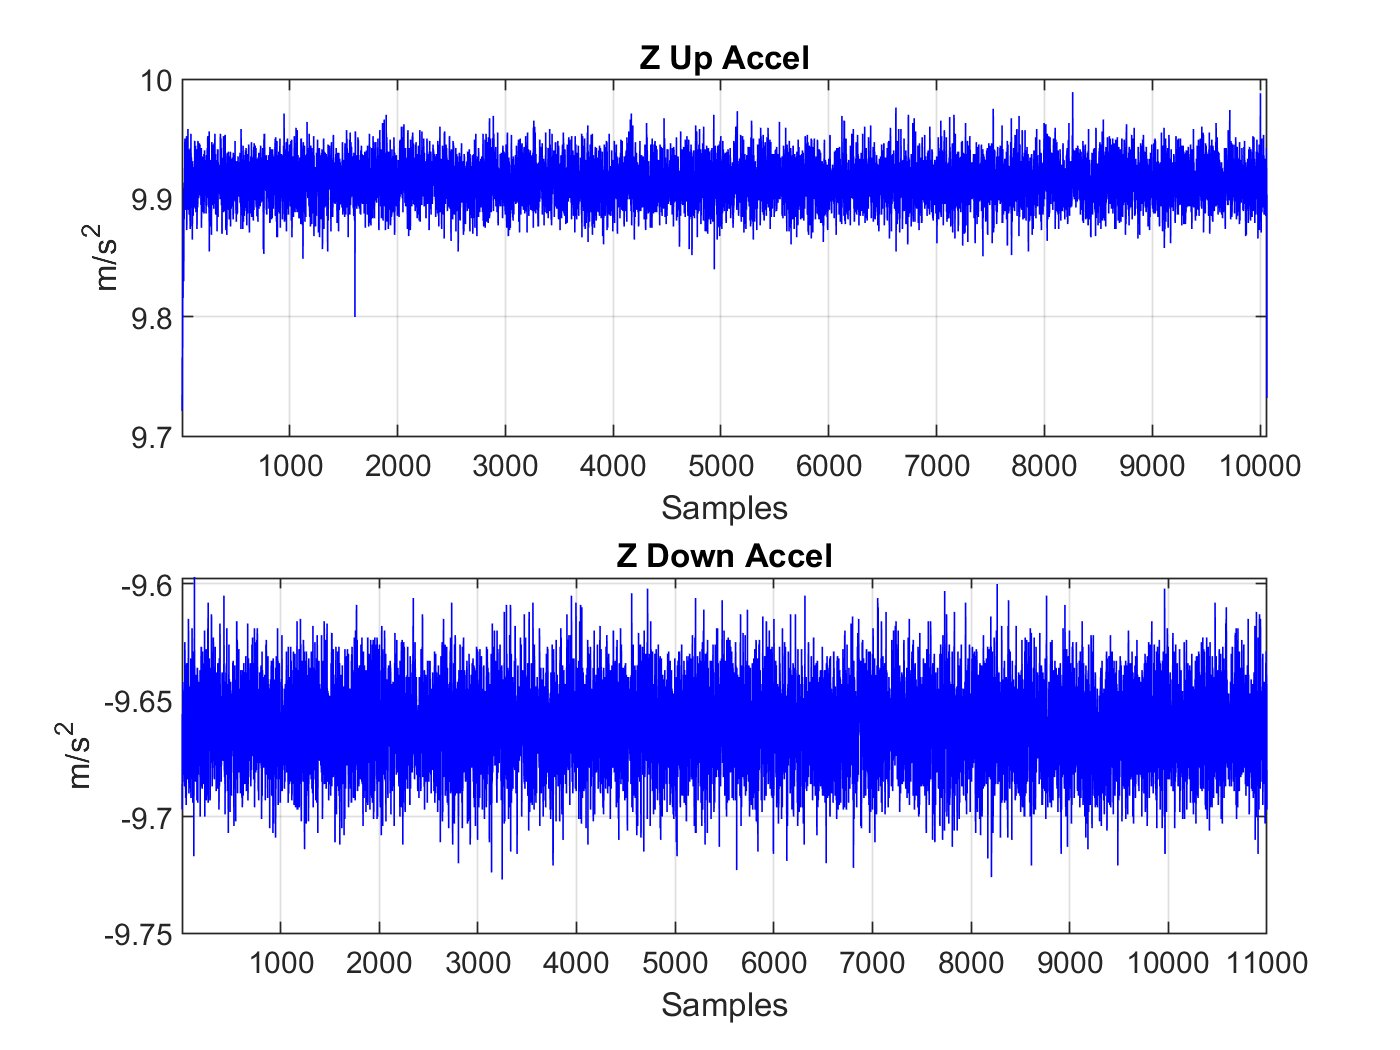


% Isolate Z Up and Z Down
mask3 = z_a > 9.7;
z_up_accel = staticzzIMU1(mask3, :);
z_down_accel = staticzzIMU1(5000:16000, :);
mask4 = z_down_accel(:,3) < -9.4;
z_down_accel = z_down_accel(mask4, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(z_up_accel(:,3), 'b')
title('Z Up Accel')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(z_up_accel)])
grid on
subplot(2,1,2)
plot(z_down_accel(:,3), 'b')
title('Z Down Accel')
xlabel('Samples')
ylabel('m/s^2')
xlim([1, length(z_down_accel)])
grid on


% Save Data
save('IMU1_accel_test.mat', 'z_up_accel', 'z_down_accel', '-append')

## Gyro Testing (30)

#### X-Gyro

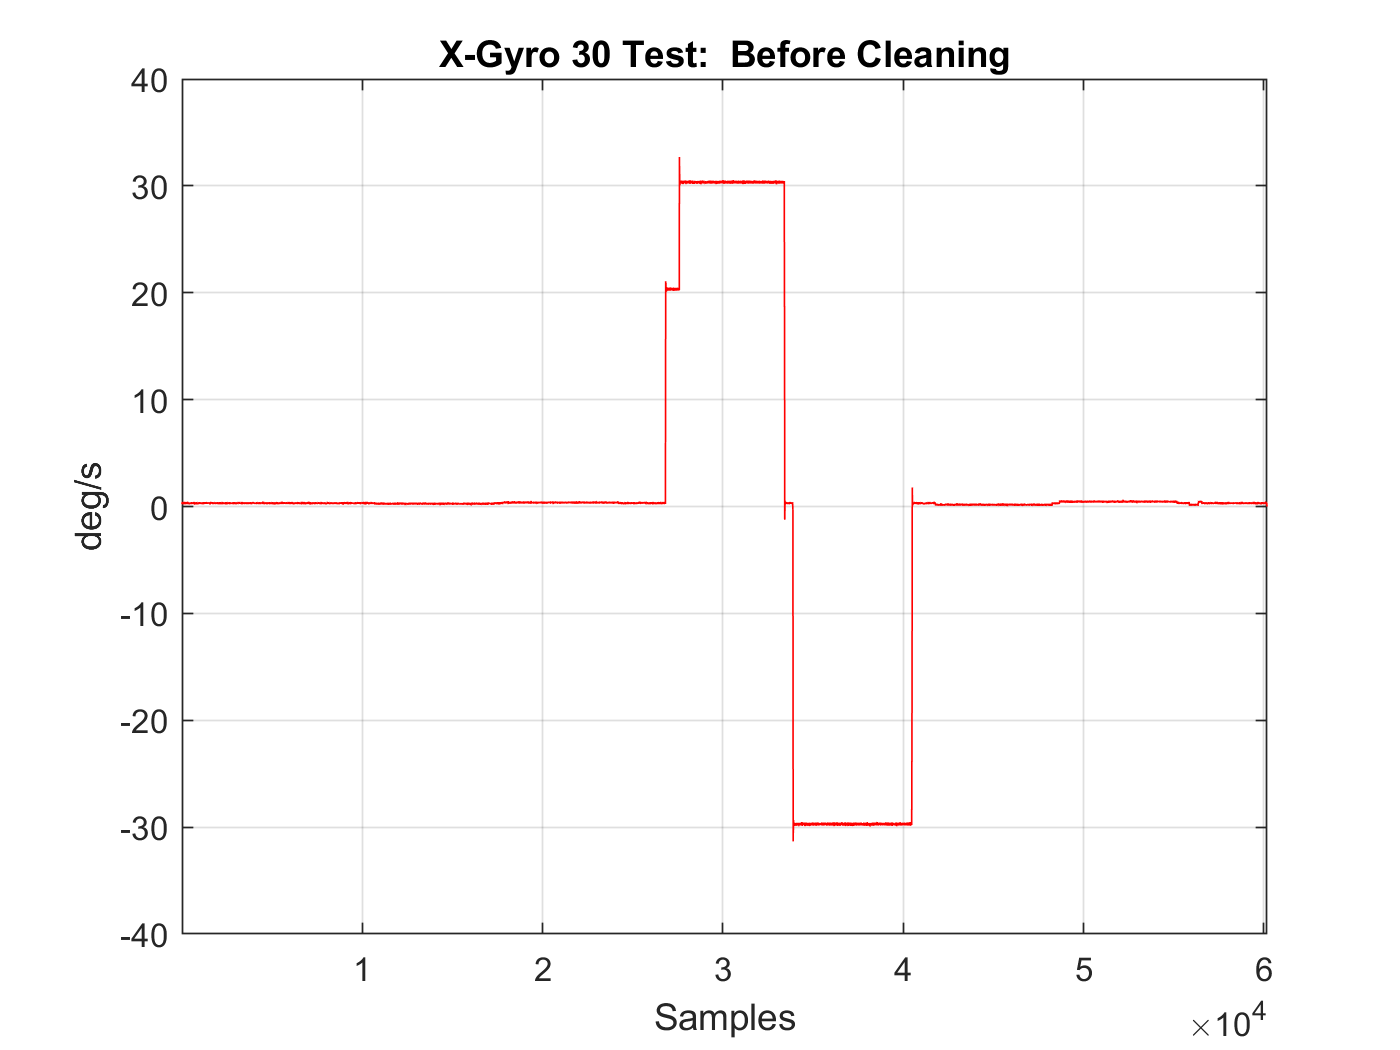

% Before Data Cleaning
x_g = gyro30zzxxyyIMU1(:,1);

figure
plot(x_g * 180/pi, 'r')
title('X-Gyro 30 Test:  Before Cleaning')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(x_g)])
grid on

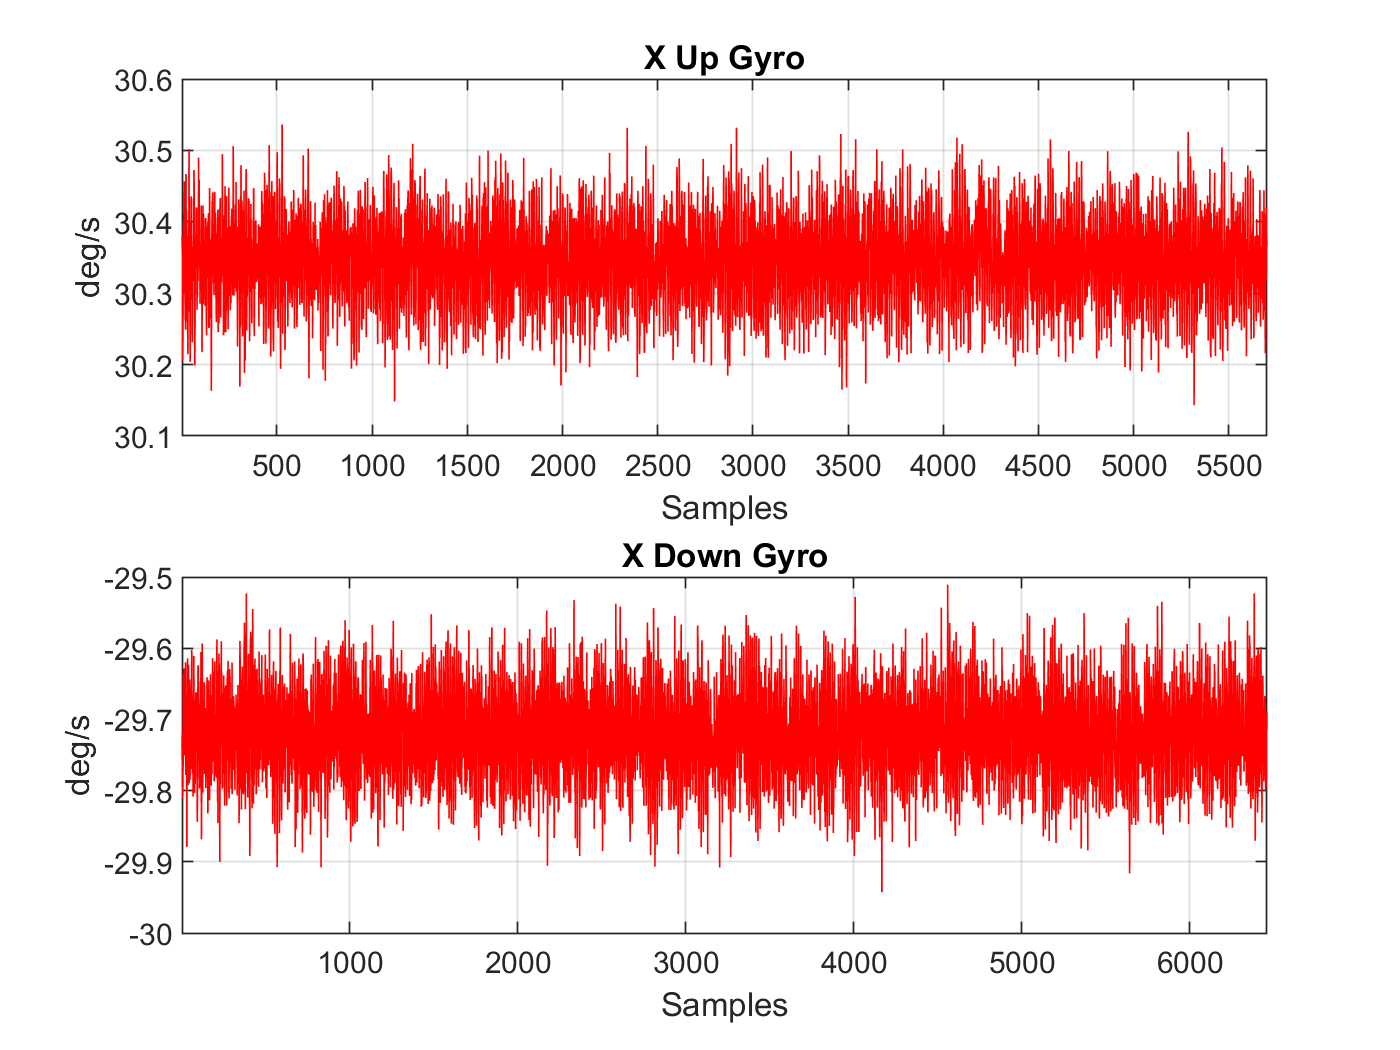


% Isolate X_pos and x_neg
x_up_gyro = gyro30zzxxyyIMU1(27650:33350, :);
x_down_gyro = gyro30zzxxyyIMU1(33990:40450, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(x_up_gyro(:,1) * 180/pi, 'r')
title('X Up Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(x_up_gyro)])
grid on
subplot(2,1,2)
plot(x_down_gyro(:,1) * 180/pi, 'r')
title('X Down Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(x_down_gyro)])
grid on


% Save Data
save('IMU1_gyro30_test.mat', 'x_up_gyro', 'x_down_gyro')

#### Y-Gyro

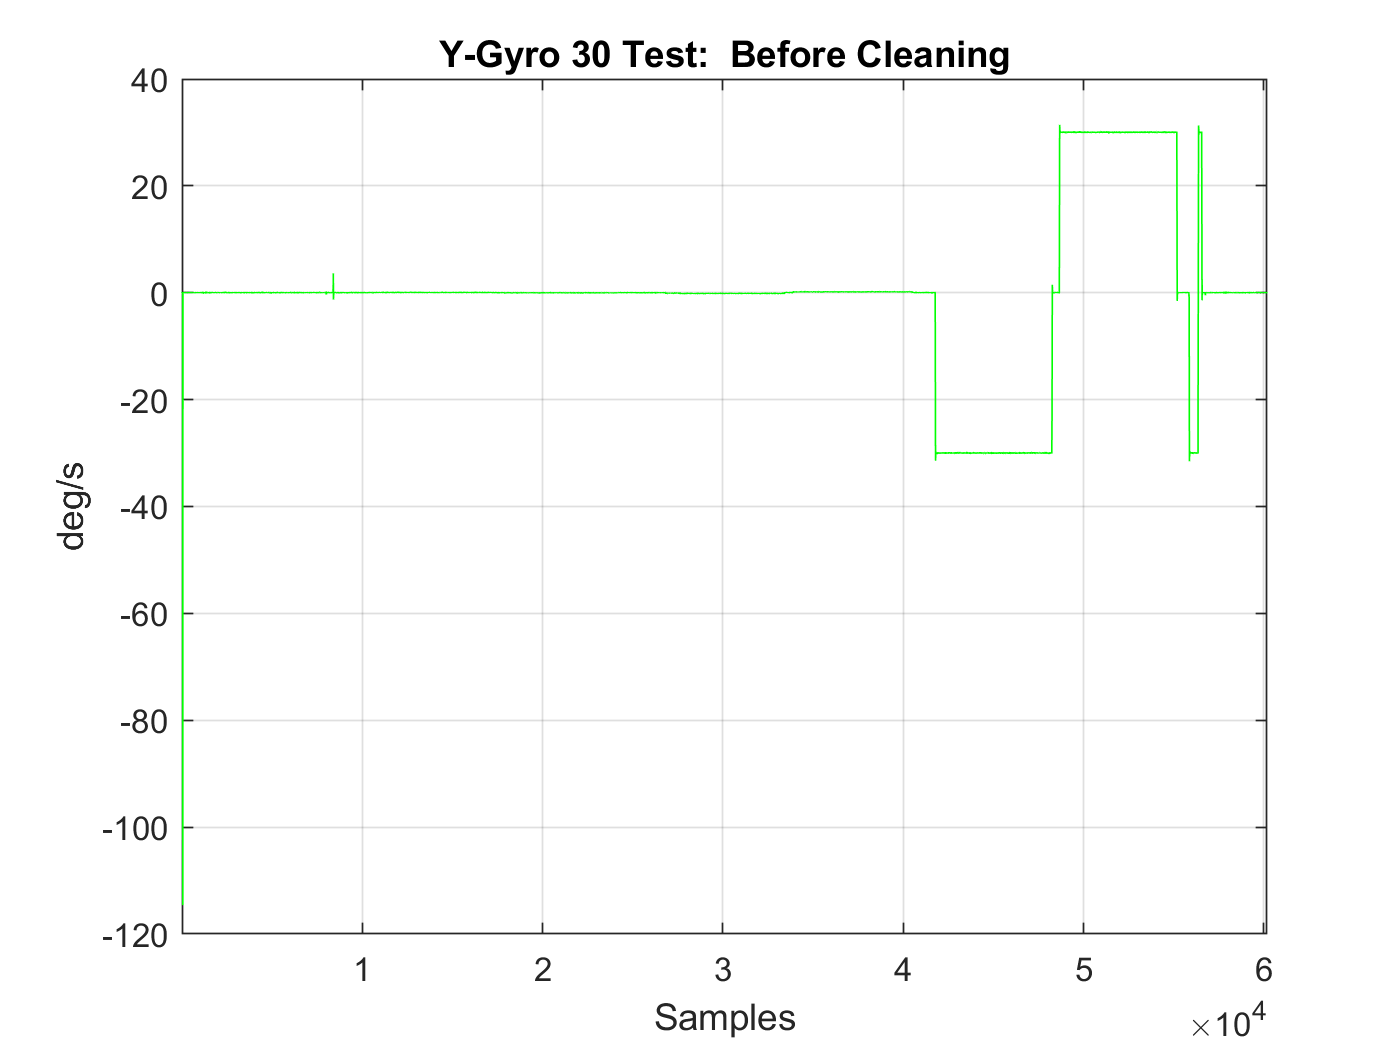

% Before Data Cleaning
y_g = gyro30zzxxyyIMU1(:,2);

figure
plot(y_g * 180/pi, 'g')
title('Y-Gyro 30 Test:  Before Cleaning')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(y_g)])
grid on

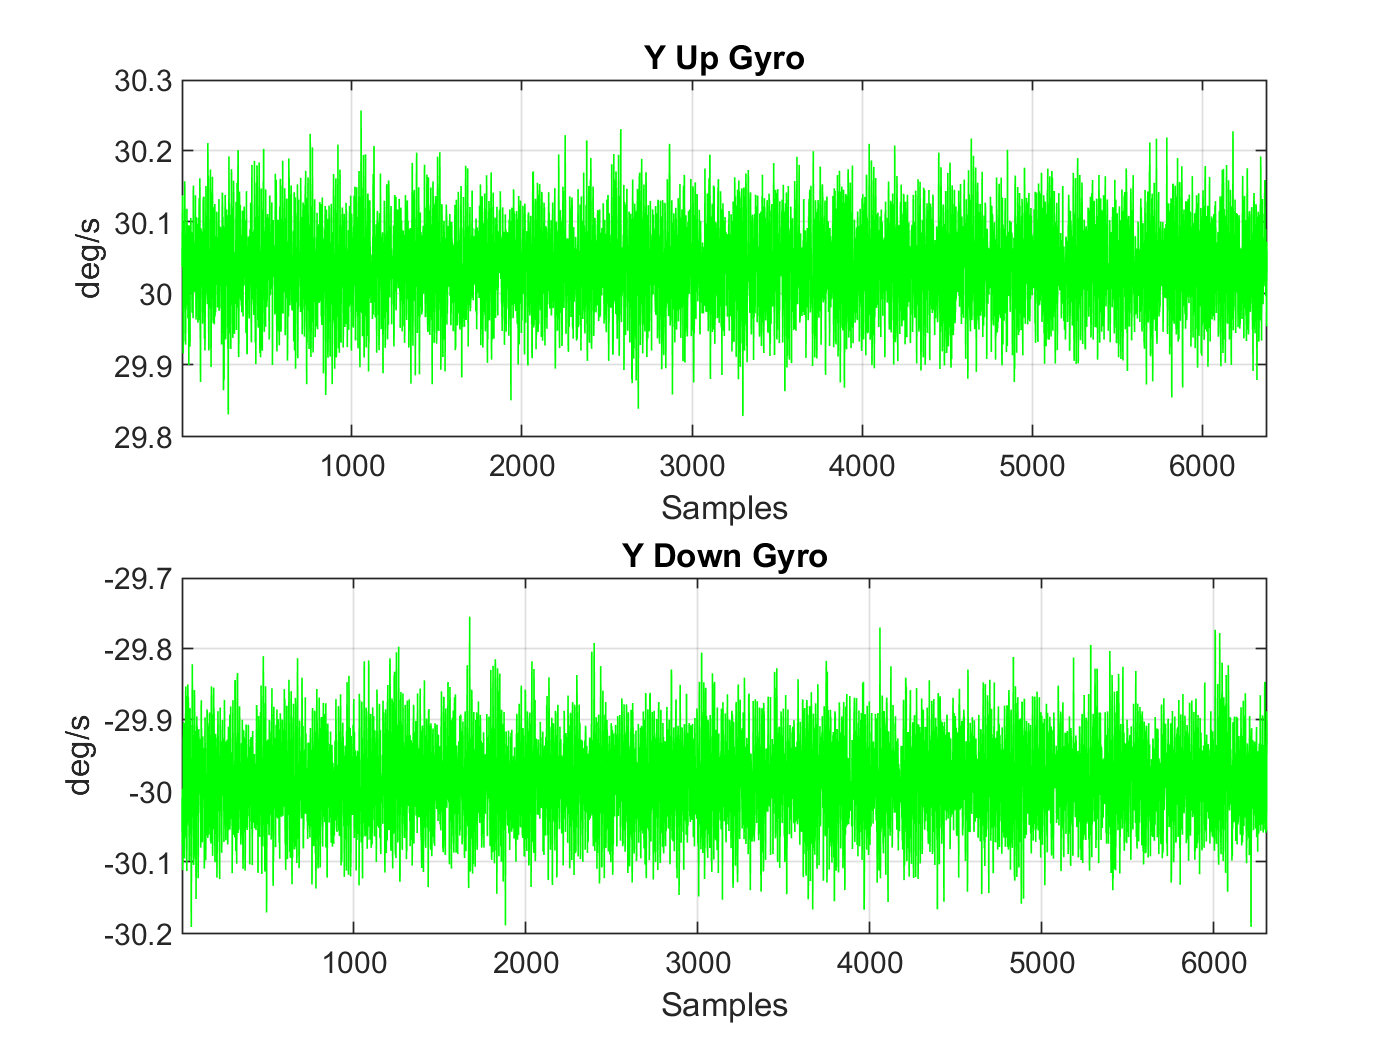


% Isolate y_pos and y_neg
y_up_gyro = gyro30zzxxyyIMU1(48740:55120, :);
y_down_gyro = gyro30zzxxyyIMU1(41860:48170, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(y_up_gyro(:,2) * 180/pi, 'g')
title('Y Up Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(y_up_gyro)])
grid on
subplot(2,1,2)
plot(y_down_gyro(:,2) * 180/pi, 'g')
title('Y Down Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(y_down_gyro)])
grid on


% Save Data
save('IMU1_gyro30_test.mat', 'y_up_gyro', 'y_down_gyro', '-append')

#### Z-Gyro

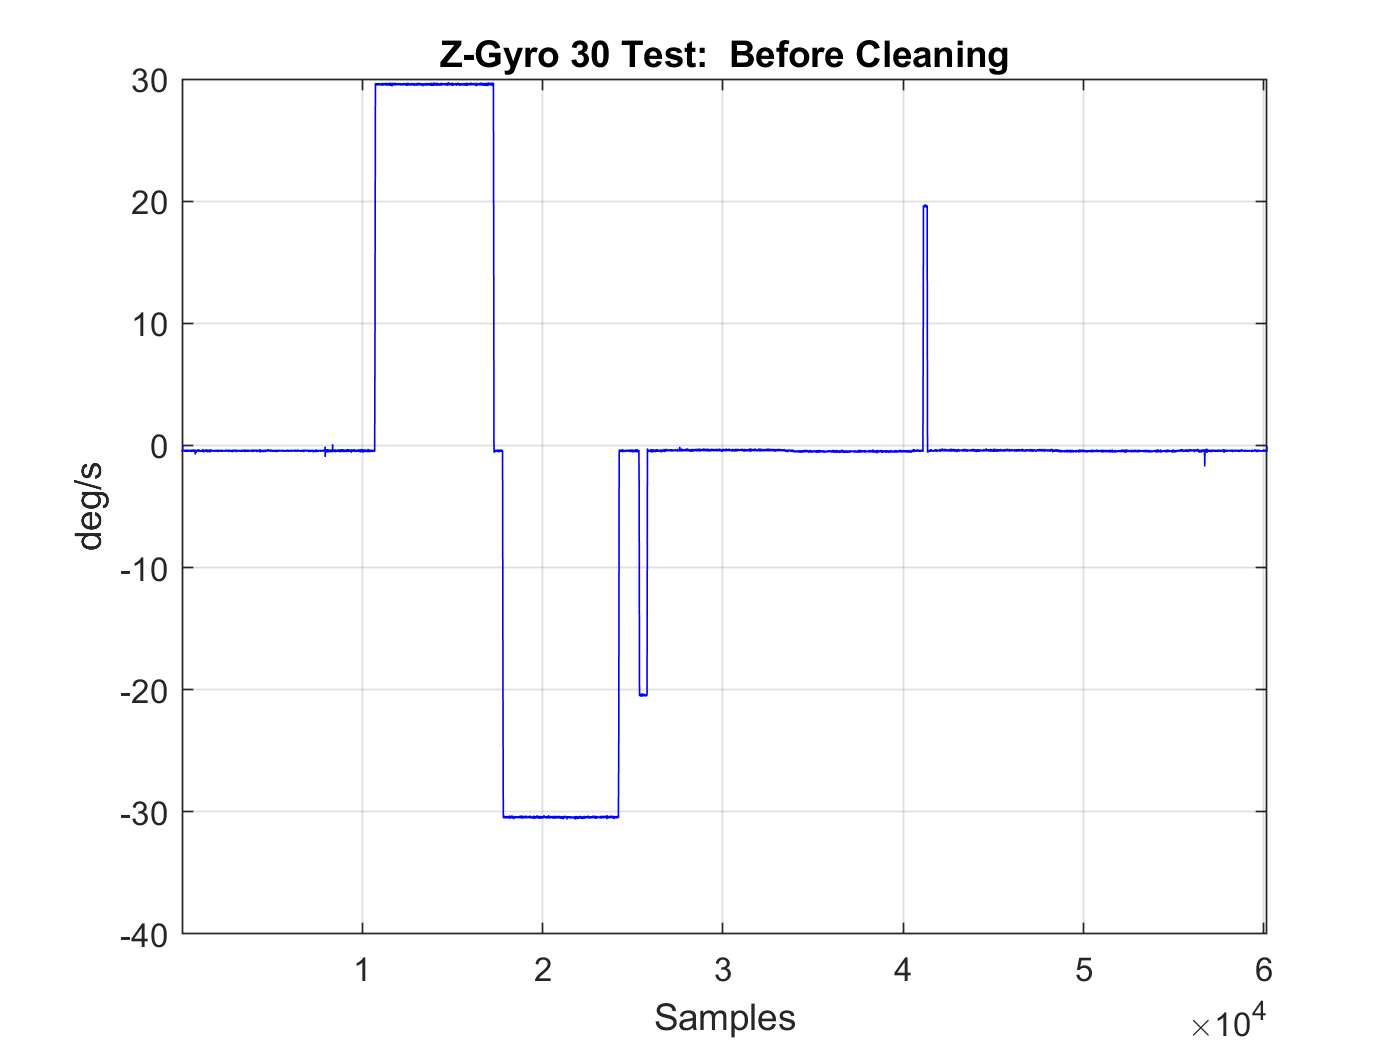

% Before Data Cleaning
z_g = gyro30zzxxyyIMU1(:,3);

figure
plot(z_g * 180/pi, 'b')
title('Z-Gyro 30 Test:  Before Cleaning')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(z_g)])
grid on

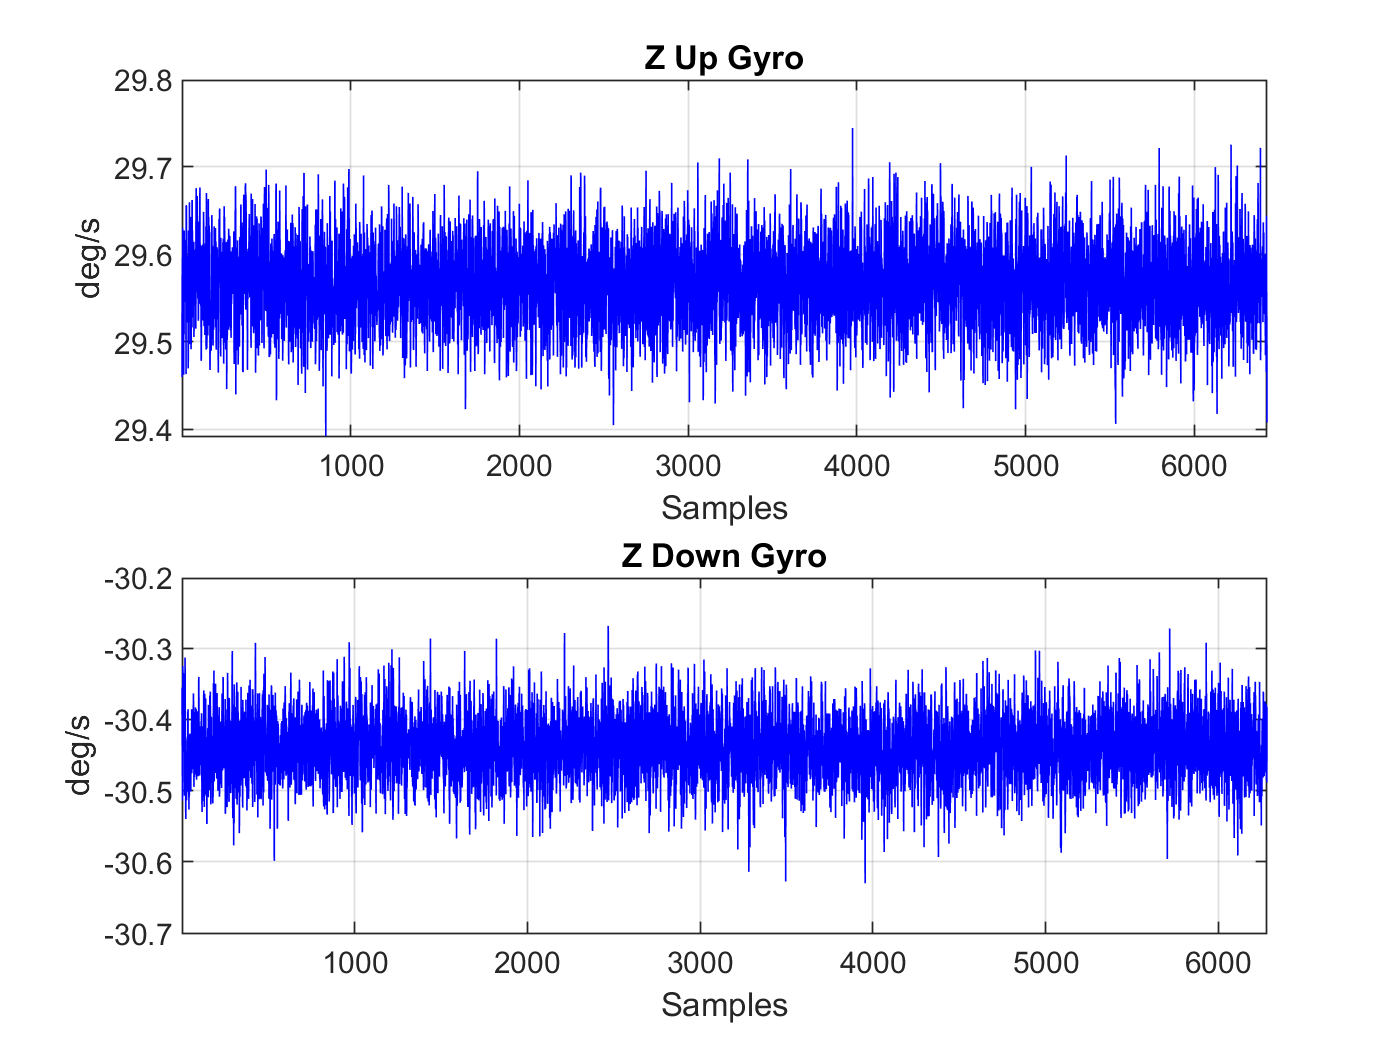


% Isolate z_pos and z_neg
z_up_gyro = gyro30zzxxyyIMU1(10790:17220, :);
z_down_gyro = gyro30zzxxyyIMU1(17860:24140, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(z_up_gyro(:,3) * 180/pi, 'b')
title('Z Up Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(z_up_gyro)])
grid on
subplot(2,1,2)
plot(z_down_gyro(:,3) * 180/pi, 'b')
title('Z Down Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(z_down_gyro)])
grid on


% Save Data
save('IMU1_gyro30_test.mat', 'z_up_gyro', 'z_down_gyro', '-append')

## Gyro Testing (60)

#### X-Gyro

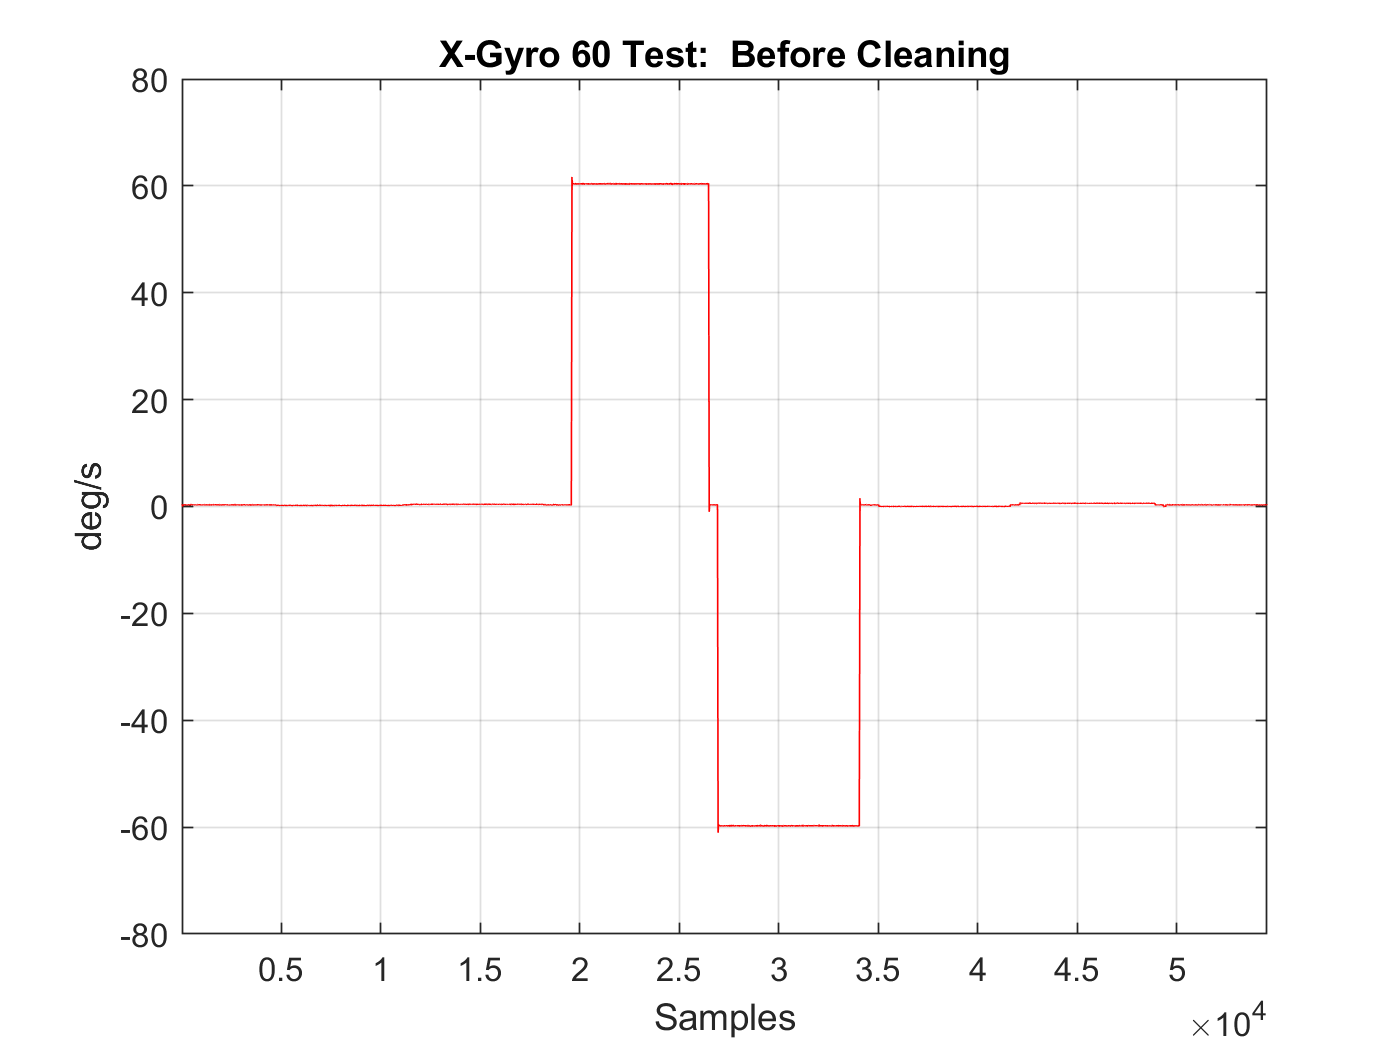

% Before Data Cleaning
x_g = gyro60zzxxyyIMU1(:,1);

figure
plot(x_g * 180/pi, 'r')
title('X-Gyro 60 Test:  Before Cleaning')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(x_g)])
grid on

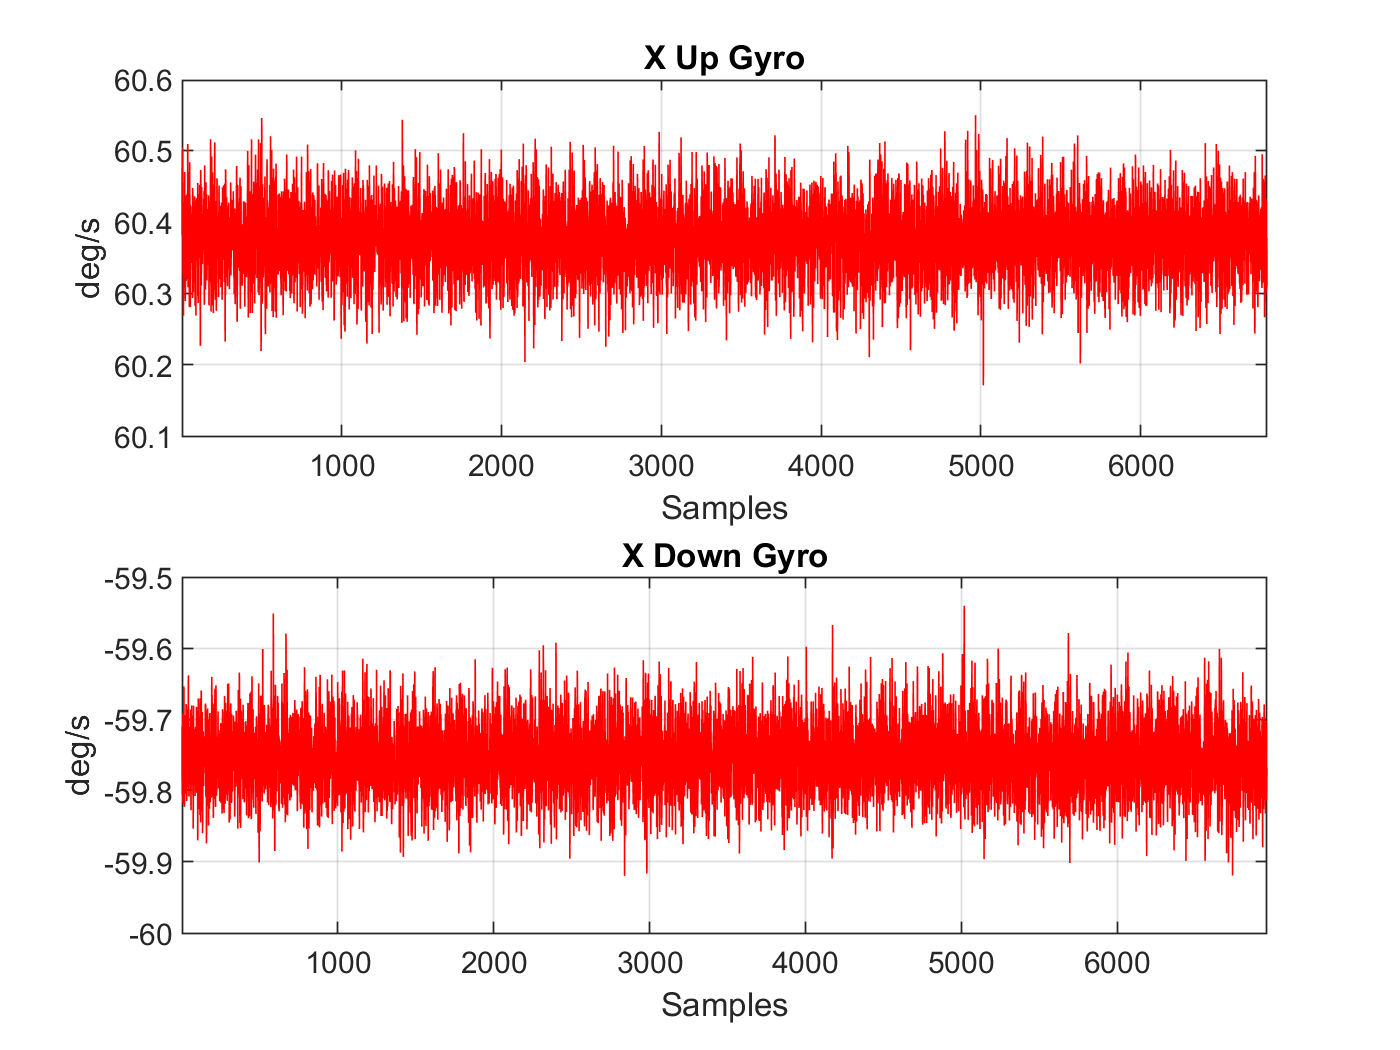


% Isolate X_pos and x_neg
x_up_gyro = gyro60zzxxyyIMU1(19620:26410, :);
x_down_gyro = gyro60zzxxyyIMU1(27020:33980, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(x_up_gyro(:,1) * 180/pi, 'r')
title('X Up Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(x_up_gyro)])
grid on
subplot(2,1,2)
plot(x_down_gyro(:,1) * 180/pi, 'r')
title('X Down Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(x_down_gyro)])
grid on


% Save Data
save('IMU1_gyro60_test.mat', 'x_up_gyro', 'x_down_gyro')

#### Y-Gyro

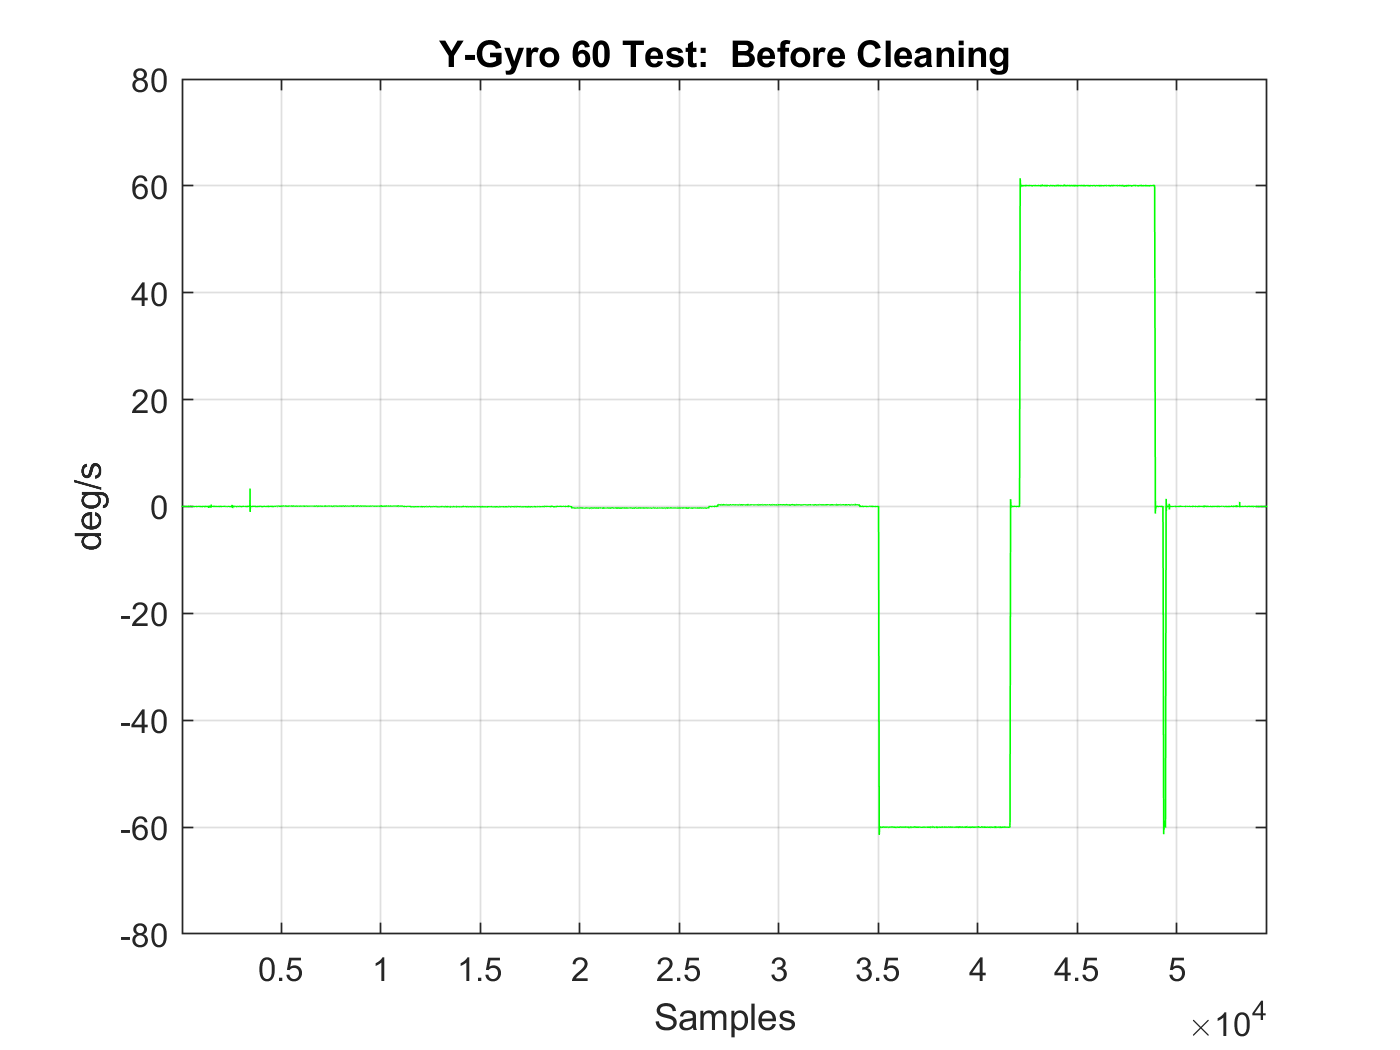

% Before Data Cleaning
y_g = gyro60zzxxyyIMU1(:,2);

figure
plot(y_g * 180/pi, 'g')
title('Y-Gyro 60 Test:  Before Cleaning')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(y_g)])
grid on

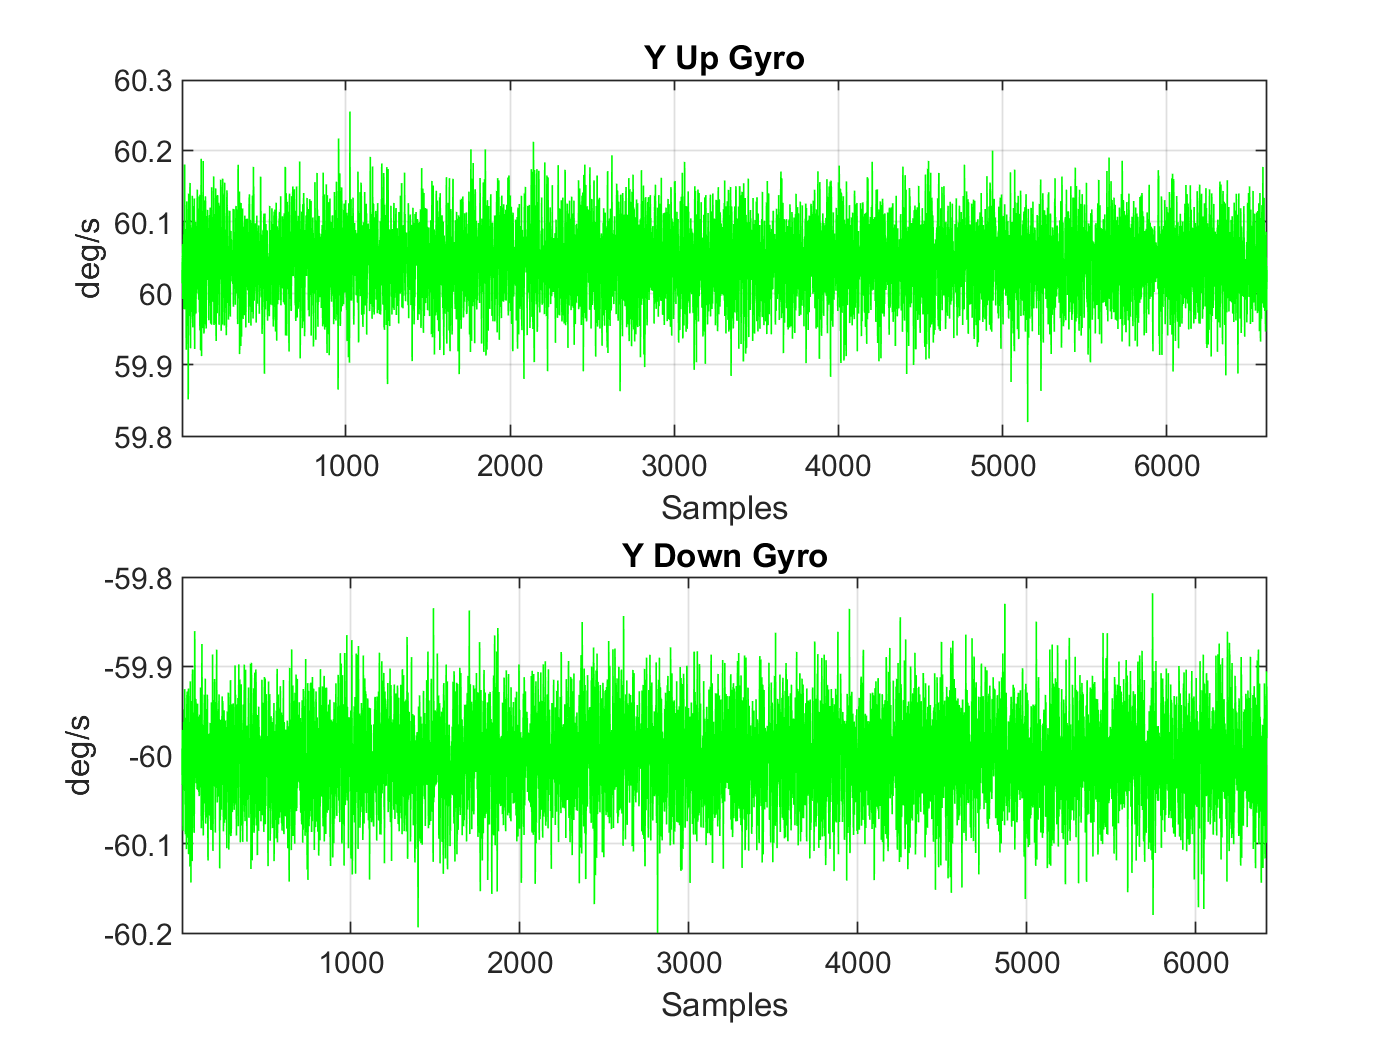


% Isolate y_pos and y_neg
y_up_gyro = gyro60zzxxyyIMU1(42210:48820, :);
y_down_gyro = gyro60zzxxyyIMU1(35140:41560, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(y_up_gyro(:,2) * 180/pi, 'g')
title('Y Up Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(y_up_gyro)])
grid on
subplot(2,1,2)
plot(y_down_gyro(:,2) * 180/pi, 'g')
title('Y Down Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(y_down_gyro)])
grid on


% Save Data
save('IMU1_gyro60_test.mat', 'y_up_gyro', 'y_down_gyro', '-append')

#### Z-Gyro

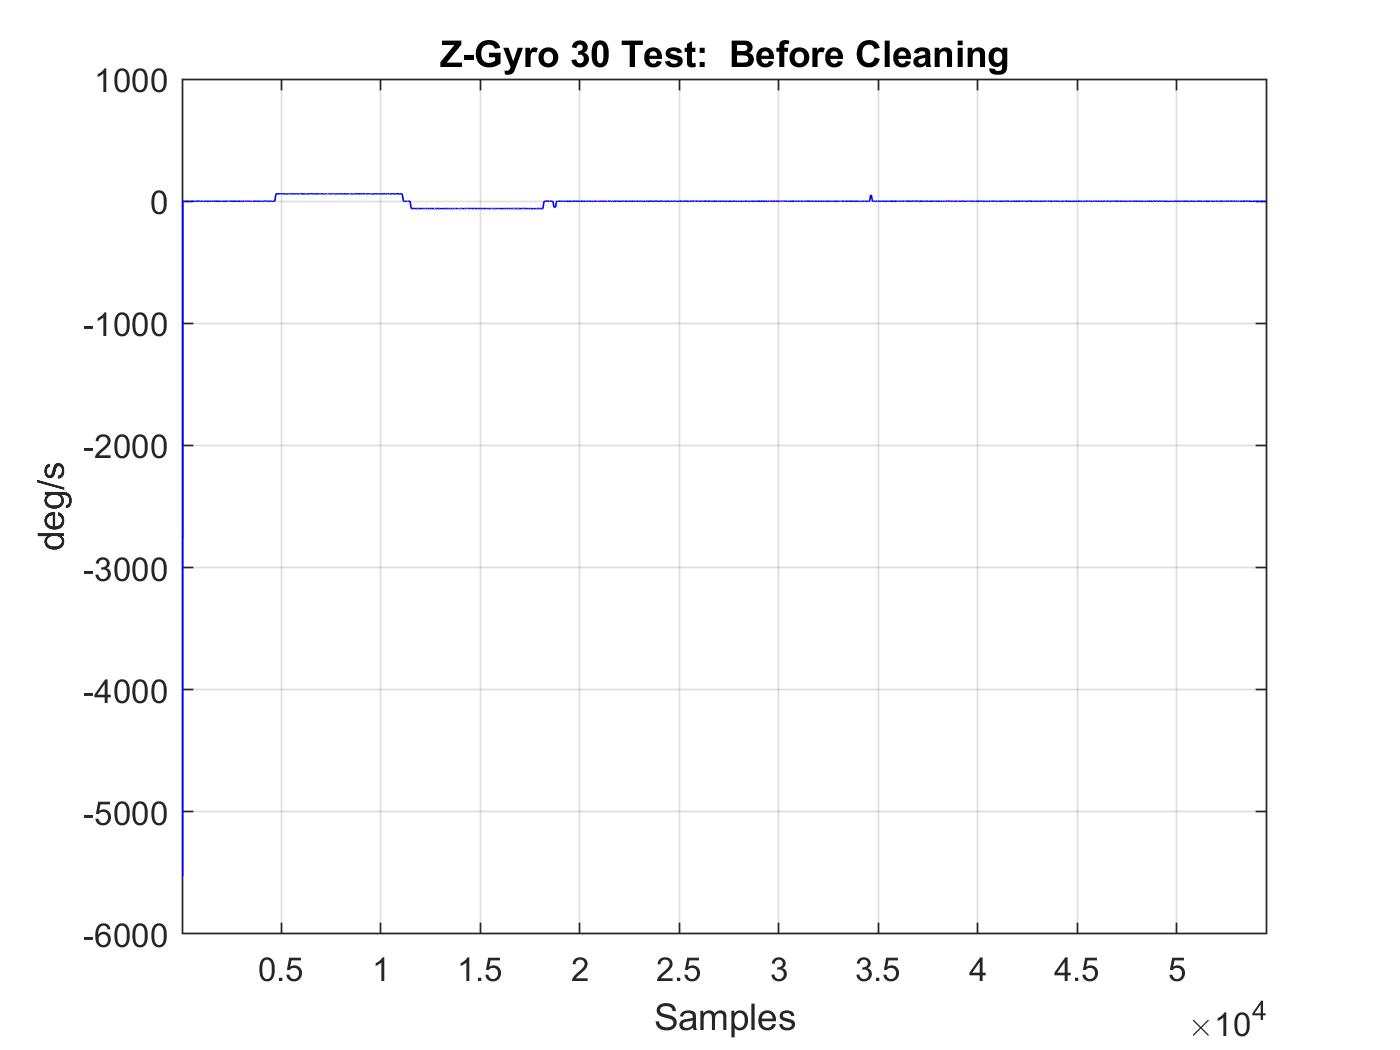

% Before Data Cleaning
z_g = gyro60zzxxyyIMU1(:,3);

figure
plot(z_g * 180/pi, 'b')
title('Z-Gyro 30 Test:  Before Cleaning')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(z_g)])
grid on

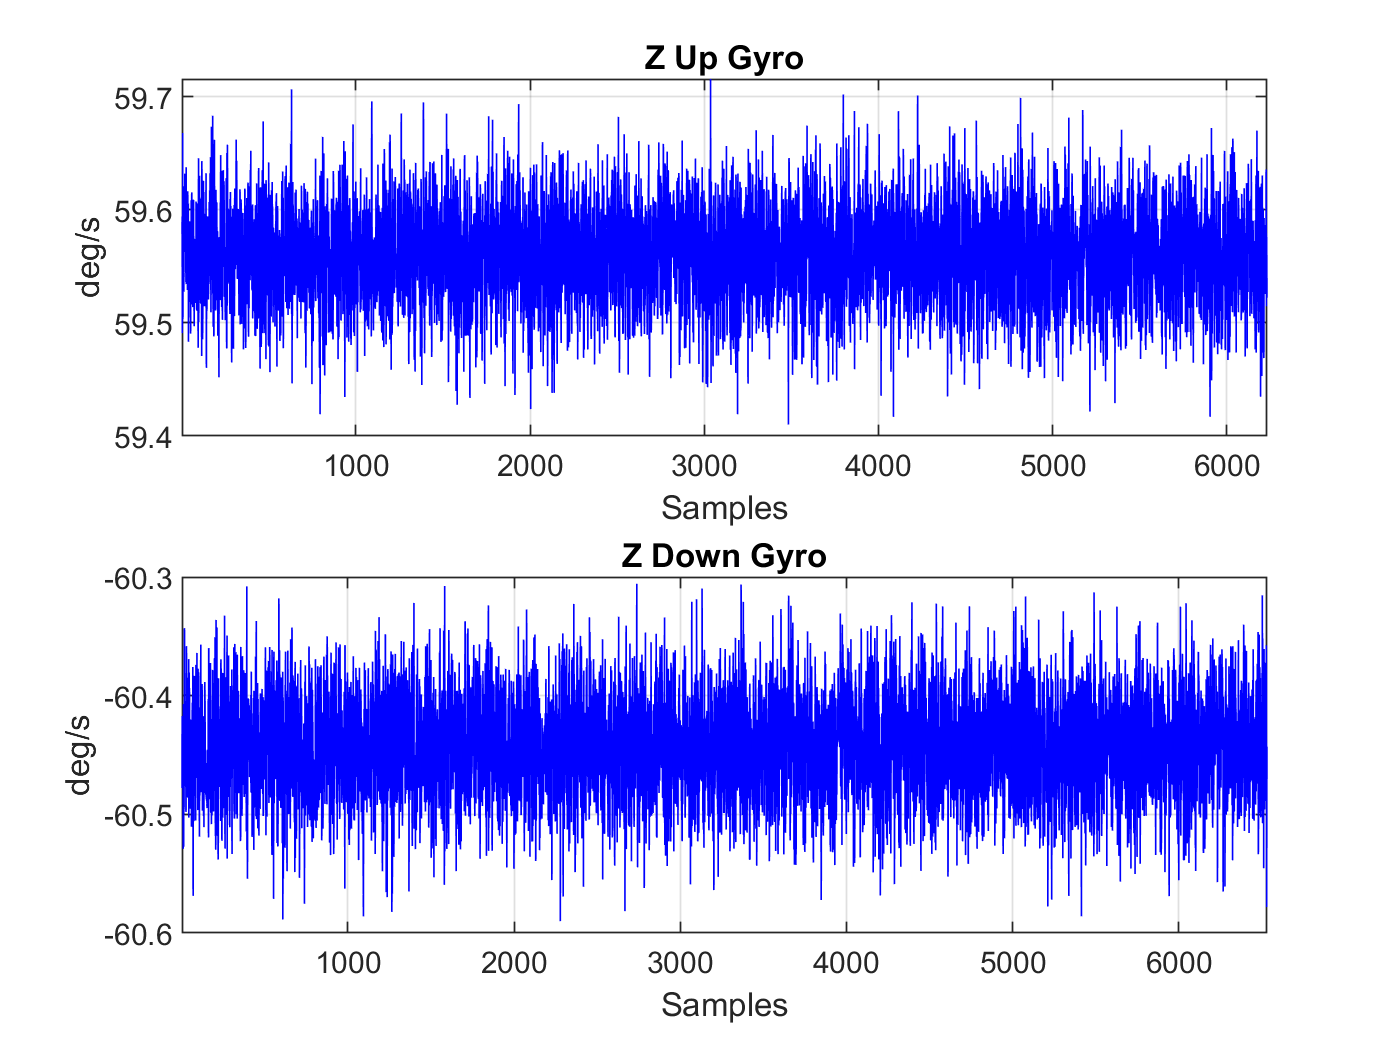


% Isolate z_pos and z_neg
z_up_gyro = gyro60zzxxyyIMU1(4770:11000, :);
z_down_gyro = gyro60zzxxyyIMU1(11590:18120, :);

% Plot Resulting Data
figure
subplot(2,1,1)
plot(z_up_gyro(:,3) * 180/pi, 'b')
title('Z Up Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(z_up_gyro)])
grid on
subplot(2,1,2)
plot(z_down_gyro(:,3) * 180/pi, 'b')
title('Z Down Gyro')
xlabel('Samples')
ylabel('deg/s')
xlim([1, length(z_down_gyro)])
grid on


% Save Data
save('IMU1_gyro60_test.mat', 'z_up_gyro', 'z_down_gyro', '-append')